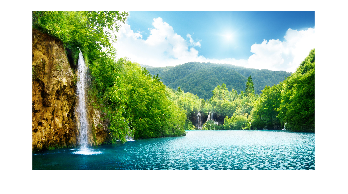

x = imread('imagem_natureza.png');
imshow(x);

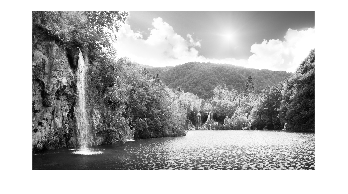

y = rgb2gray(x);
imshow(y);

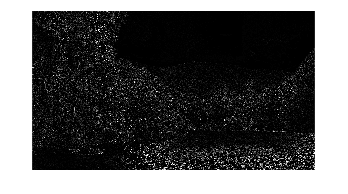

y = double(y)/255;
h = [-1 -1 -1; -1 8 -1 ; -1 -1 -1]; %Passa alta 2d
z = conv2(y,h,'same');
imshow(z);

N = 5;
h = ones(N,N)/N^2;
imshow(z);

N = 25;
h = ones(N,N)/N^2;
imshow(z);

N = 55;
h = ones(N,N)/N^2;
imshow(z);

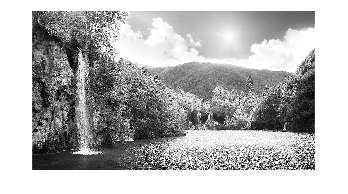

y_bordas = y-z;
imshow(y_bordas);

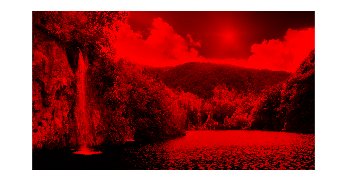

x_r = x;
x_r(:,:,2) = 0;
x_r(:,:,3) = 0;
imshow(x_r);

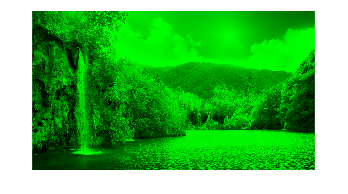

x_g = x;
x_g(:,:,1) = 0;
x_g(:,:,3) = 0;
imshow(x_g);

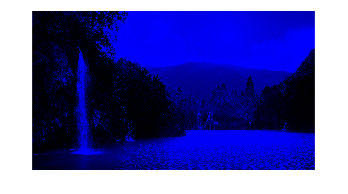

x_b = x;
x_b(:,:,1) = 0;
x_b(:,:,2) = 0;
imshow(x_b);

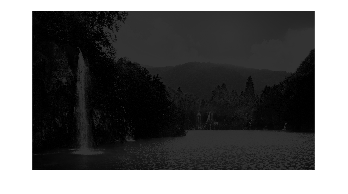

x2 = x(:,:,1).*0.1;
x2 = x(:,:,2).*0.7;
x2 = x(:,:,3).*0.2;
imshow(x2);

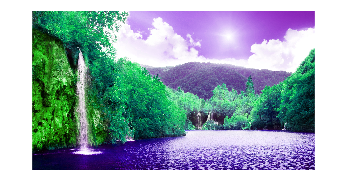

x_hsi = rgb2hsv(x);
%link ufop http://www.decom.ufop.br/guillermo/BCC326/slides/Processamento%20de%20Imagens%20-%20Sistema%20de%20Cores.pdf
x_hsi(:,:,1) = x_hsi(:,:,1)+0.2;
x_hsi2 = hsv2rgb(x_hsi);
imshow(x_hsi2);